# describing functions

## step 1: what are the higher order fourier coeffs?


% see notebook p94-95

% i = harmonic (1 is fundamental)
% N = saturation level
% k = slope of non-saturated signal
% a = amplitude of input sinusoid
clear all
syms i real integer positive 
syms N a k wt real positive
%syms sat(x)
%sat(x) = piecewise(abs(x)<1, x, sign(x)*1);
unsat_integrand = sin(wt)*k*a/N * sin(i * wt);
wt_s = asin(N/(a*k));

bi = 2*N/pi * ( int(unsat_integrand,wt, 0, wt_s) + ...
                int(sin(i*wt),wt, wt_s, pi-wt_s) + ...
                int(unsat_integrand,wt, pi-wt_s, pi));
Keq = simplify(bi / a)

$$Keq = \begin{array}{l} \left\{ \begin{array}{cl} \frac{2\,N\,\sigma_{1}+2\,a^{2}\,k^{2}\,\sigma_{2}}{\sigma_{5}} & \text{ if }i=1\\ \frac{\left(N\,\cos\left(i\,\sigma_{2}\right)-i\,\sin\left(i\,\sigma_{2}\right)\,\sigma_{1}\right)\,\left(2\,{\left(-1\right)}^{i}-2\right)}{a\,i\,\pi \,\left(i^{2}-1\right)} & \text{ if }i\neq 1\\ -\frac{N\,\sigma_{1}-\pi \,a^{2}\,k^{2}}{\sigma_{5}} & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge i=1\\ \frac{i\,k\,\left(\pi \,i^{2}-\pi +4\,\cos\left(\frac{\pi \,i}{2}\right)\,\sigma_{3}\,\sigma_{4}\right)}{2\,\pi \,\sigma_{3}\,\sigma_{4}\,\left(i-1\right)\,\left(i+1\right)} & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge i\neq 1\\ 0 & \text{ if }\sigma_{2}=\frac{\pi }{2}\wedge 2\leq i\wedge i\in \left\{2\,l+1|l\in \mathbb{Z}\right\} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{2}\,k^{2}-N^{2}}\\ \sigma_{2}=\mathrm{asin}\left(\frac{N}{a\,k}\right)\\ \sigma_{3}=\Gamma (\frac{3}{2}-\frac{i}{2})\\ \sigma_{4}=\Gamma (\frac{i}{2}+\frac{3}{2})\\ \sigma_{5}=a^{2}\,k\,\pi \end{array}$$

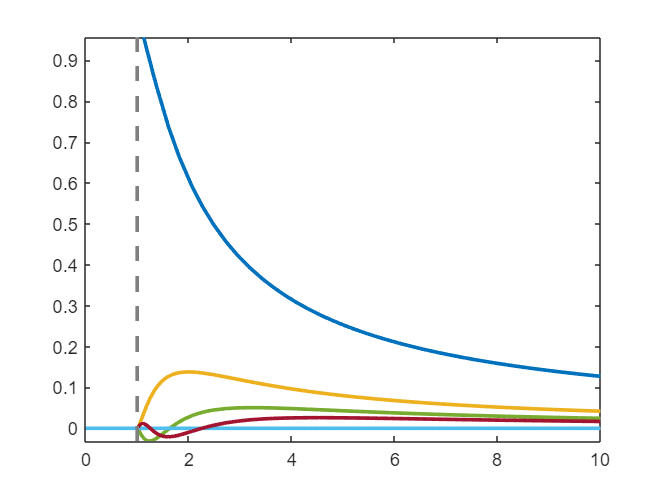


harmonics = 1:7;
for ii=harmonics
    Ki(ii) = simplify(subs(Keq,i,ii));
end

Ki = subs(Ki, [N,k],[1,1]);
% Keq plot
figure
fplot(Ki,[0,10],'LineWidth',2)

ax = gca;
ax.LineStyleCyclingMethod = 'withcolor'; 

Unrecognized property 'LineStyleCyclingMethod' for class 'matlab.graphics.axis.Axes'.

ylim([-0.1,1.1])
xlabel('Saturation Amplitude Ratio $|I_{L,temp}|/I_{max}$','Interpreter','latex')
ylabel('Saturation Factor $f_{sat,n}$','Interpreter','latex')
lgd = legend(strsplit(num2str(harmonics)));
title(lgd,'harmonic n')

% Keq/Keq(1) plot (comparison of harmonics to fundamental)
figure
fplot(Ki/Ki(1),[0,10])
ylim([-0.1,1.1])
xlabel('Saturation Amplitude Ratio $|I_{L,temp}|/I_{max}$','Interpreter','latex')
ylabel('Ratio to Fundamental, $f_{sat,n}/f_{sat,1}$','Interpreter','latex')
lgd = legend(strsplit(num2str(harmonics)));
title(lgd,'harmonic n')

% total harmonic distortion plot
% if enough harmonics, should asymptote to 48.3% (square wave)
fplot(sqrt(sum(Ki(2:end).^2))/Ki(1),[0 10])
xlabel('Saturation Amplitude Ratio F_p/F_{max}')
ylabel('Total Harmonic Distortion')


## step 2: what is I_temp?

syms V_th I_max I_temp_mag I_temp_phase real positive
syms Re_Z_th real positive
syms alpha real
syms c real

assumeAlso(I_max < I_temp_mag)

I = I_max / I_temp_mag;
f_sat_1 = subs(Ki(1),a,1/I)

$$f\_sat\_1 = \frac{{I_{\max}}^{2}\,\left(2\,\sqrt{\frac{{I_{\mathrm{temp},\mathrm{mag}}}^{2}}{{I_{\max}}^{2}}-1}+\frac{2\,{I_{\mathrm{temp},\mathrm{mag}}}^{2}\,\mathrm{asin}\left(\frac{I_{\max}}{I_{\mathrm{temp},\mathrm{mag}}}\right)}{{I_{\max}}^{2}}\right)}{{I_{\mathrm{temp},\mathrm{mag}}}^{2}\,\pi }$$


Z_th = Re_Z_th * (1 + 1i * alpha);
Z_L = Z_th';
I_temp = I_temp_mag * exp(1i * I_temp_phase);
V_s = V_th - Z_L * I_temp;
I_1 = V_s / Z_th;
f_sat_mag_eqn = f_sat_1 == c;%abs(I_1 / I_temp);
solve(f_sat_mag_eqn,I_temp_mag,'IgnoreAnalyticConstraints',true)

 
ans =
 
Empty sym: 0-by-1
 


f_sat_phs_eqn = angle(I_1) == angle(I_temp);
solve(f_sat_phs_eqn,I_temp_phase,'IgnoreAnalyticConstraints',true)

 
ans =
 
Empty sym: 0-by-1
 


sol = solve([f_sat_mag_eqn,f_sat_phs_eqn], [I_temp_mag,I_temp_phase],'ReturnConditions',true)

sol = struct with fields:
      I_temp_mag: z
    I_temp_phase: z1
      parameters: [z    z1]
      conditions: I_max < z & (I_max^2*(2*(z^2/I_max^2 - 1)^(1/2) + (2*z^2*asin(I_max/z))/I_max^2))/(z^2*pi) - c == 0 & angle((V_th + Re_Z_th*z*exp(z1*1i)*(- 1 + alpha*1i))/(1 + alpha*1i)) - angle(exp(z1*1i)) == 0 & 0 < z1


% m = sol.parameters(1);
% I_phase = simplify(sol.I_temp_phase-2*pi*m,'Criterion','preferReal')
sol.conditions

$$ans = I_{\max}<z\wedge \frac{{I_{\max}}^{2}\,\left(2\,\sqrt{\frac{z^{2}}{{I_{\max}}^{2}}-1}+\frac{2\,z^{2}\,\mathrm{asin}\left(\frac{I_{\max}}{z}\right)}{{I_{\max}}^{2}}\right)}{z^{2}\,\pi }-c=0\wedge \text{angle}\left(\frac{V_{\mathrm{th}}+\Re_{Z,\mathrm{th}}\,z\,{\mathrm{e}}^{z_{1}\,\mathrm{i}}\,\left(-1+\alpha \,\mathrm{i}\right)}{1+\alpha \,\mathrm{i}}\right)-\text{angle}\left({\mathrm{e}}^{z_{1}\,\mathrm{i}}\right)=0\wedge 0<z_{1}$$

% polynomial approximation of the first describing function
syms x
f = asin(x)/x + sqrt(1-x^2);
tay = taylor( f,'Order',10)

$$tay = -\frac{5\,x^{8}}{576}-\frac{x^{6}}{56}-\frac{x^{4}}{20}-\frac{x^{2}}{3}+2$$

s6 = series(f,'Order',10)

$$s6 = -\frac{5\,x^{8}}{576}-\frac{x^{6}}{56}-\frac{x^{4}}{20}-\frac{x^{2}}{3}+2$$

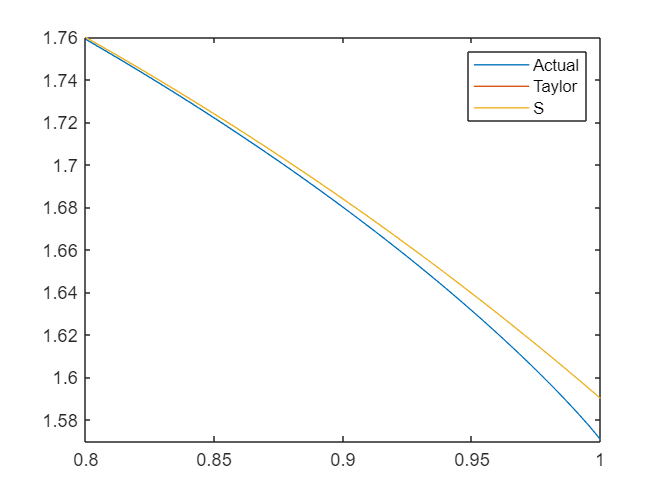

fplot([f tay s6],[.8 1])
legend('Actual','Taylor','S')

% step 3: what is their effect on energy and body amplitude?


